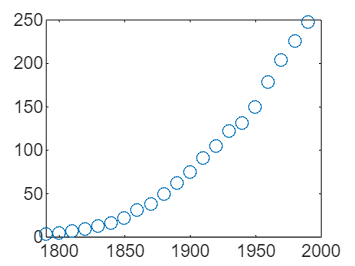

load census.mat         % 載入人口資料
plot(cdate, pop, 'o');  % cdate代表年度，pop代表人口總數


% census03
theta = polyfit(cdate, pop, 2);

% census01
% A = [ones(size(cdate)), cdate, cdate.^2];
y = pop;
% theta = A\y;           % 利用'左除'，找出最佳的 theta 值

A = theta .\ y;          % theta 已算出，當作已知找出A

% t = 2000; pop2000 = [1, t, t^2] * theta;
%             % 在 2000 年美國人口線數預測值
% t = 2010; pop2010 = [1, t, t^2] * theta;
%             % 在 2000 年美國人口線數預測值
fprintf('美國人口在2000年的預測值 = %g (百萬人) \n', pop2000);

美國人口在2000年的預測值 = 274.622 (百萬人) 


fprintf('美國人口在2010年的預測值 = %g (百萬人) \n', pop2010);

美國人口在2010年的預測值 = 301.824 (百萬人) 


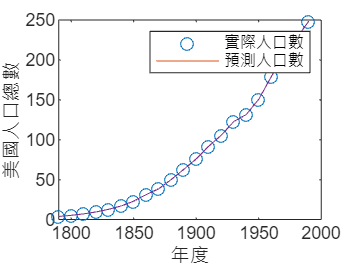


plot(cdate, pop, 'o', cdate, A .* theta, '-');
legend('實際人口數', '預測人口數')
xlabel('年度');
ylabel('美國人口總數');